# 034IN - FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL - A.Y. 2023-2024

# Full Examination - June 21 2024

# PART 2 - Design of a Controller 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

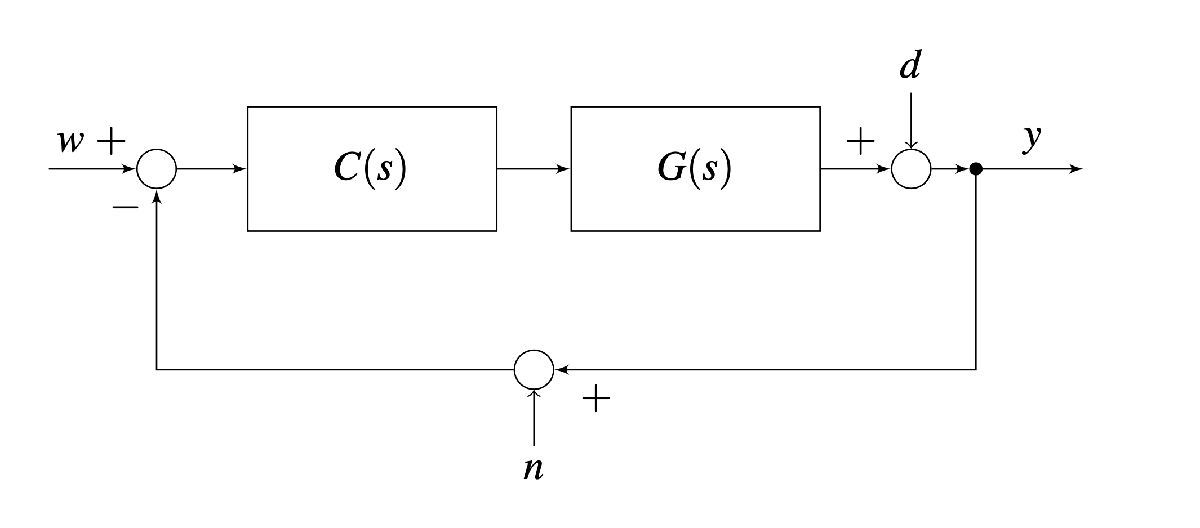	

where $G(s)$ is given by                


$$G(s) = \frac{4.815 \, (1+20\,s)}{(1+0.125\,s)^2}$$


## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $\left\vert e(\infty) \right\vert = 0$ for $w(t) = \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function; 

- For $d(t)=D \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall D \in \mathbb{R}, \; D>0$, $\omega \in \left[0.1\,,\; 1.0\right]\;\text{rad/s}$, the corresponding steady-state output $y_{d,\,\infty}(t)$ generated by the disturbance $d(t)$, with $w(t)=0$, $n(t)=0$, $\forall t$ has magnitude satisfying $|y_{d,\,\infty}(t)| \le D/20$;

- For $n(t) = N \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall N \in \mathbb{R},\;N>0$, $\omega \in \left[600,\,1200\right]\;\text{rad/s}$, the corresponding steady-state output $y_{n,\,\infty}(t)$ generated by the disturbance $n(t)$, with $w(t)=0$, $d(t)=0$, $\forall t$ has magnitude satisfying $|y_{n,\,\infty}(t)| \le N/25$.

- The phase margin satisfies $\varphi_m \ge 40^{\degree}$.

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

### A1: Answer to Question Q1

#### The Static Design					

To meet Requirement (Q1.1), the open-loop transfer function $L(s)$ has to be of type $g\ge 1$.  

We **choose **$g=1$ to keep the controller as simple as possible and, more important, to minimise the negative phase contribution that would reduce significantly the phase margin. 

Assuming 


$$C(s) = C_1(s) \cdot C_2(s)\,,\quad C_1(s) = \frac{\mu_C}{s}\,,\quad  C_2(0) =1$$


the **static design** leeds to 


$$L(s) = 4.815 \,\mu_{C}\,\frac{ (1+20\,s)}{s(1+0.125\,s)^2}$$


**Stability and Performance of the Closed-Loop System**

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 4.815*(1+20*s)/((1+0.125*s)^2); % the process G(s)

muC1 = 1; % first trial
C1s = muC1/s; % a pure I controler (the static controller)
C2s = tf(1); % the dynamic controller: a pure P gain
Cs = C1s * C2s;

L1s = Cs*Gs; % the open-loop TF
zL1 = zero(L1s);
pL1 = pole(L1s);

**First Analysis**: Explore the Root Locus of $L_1(s)$, looking for a feasible solution (i.e. by modifying only the gain constant of $C(s)$ am I able to meet all the requirements?)

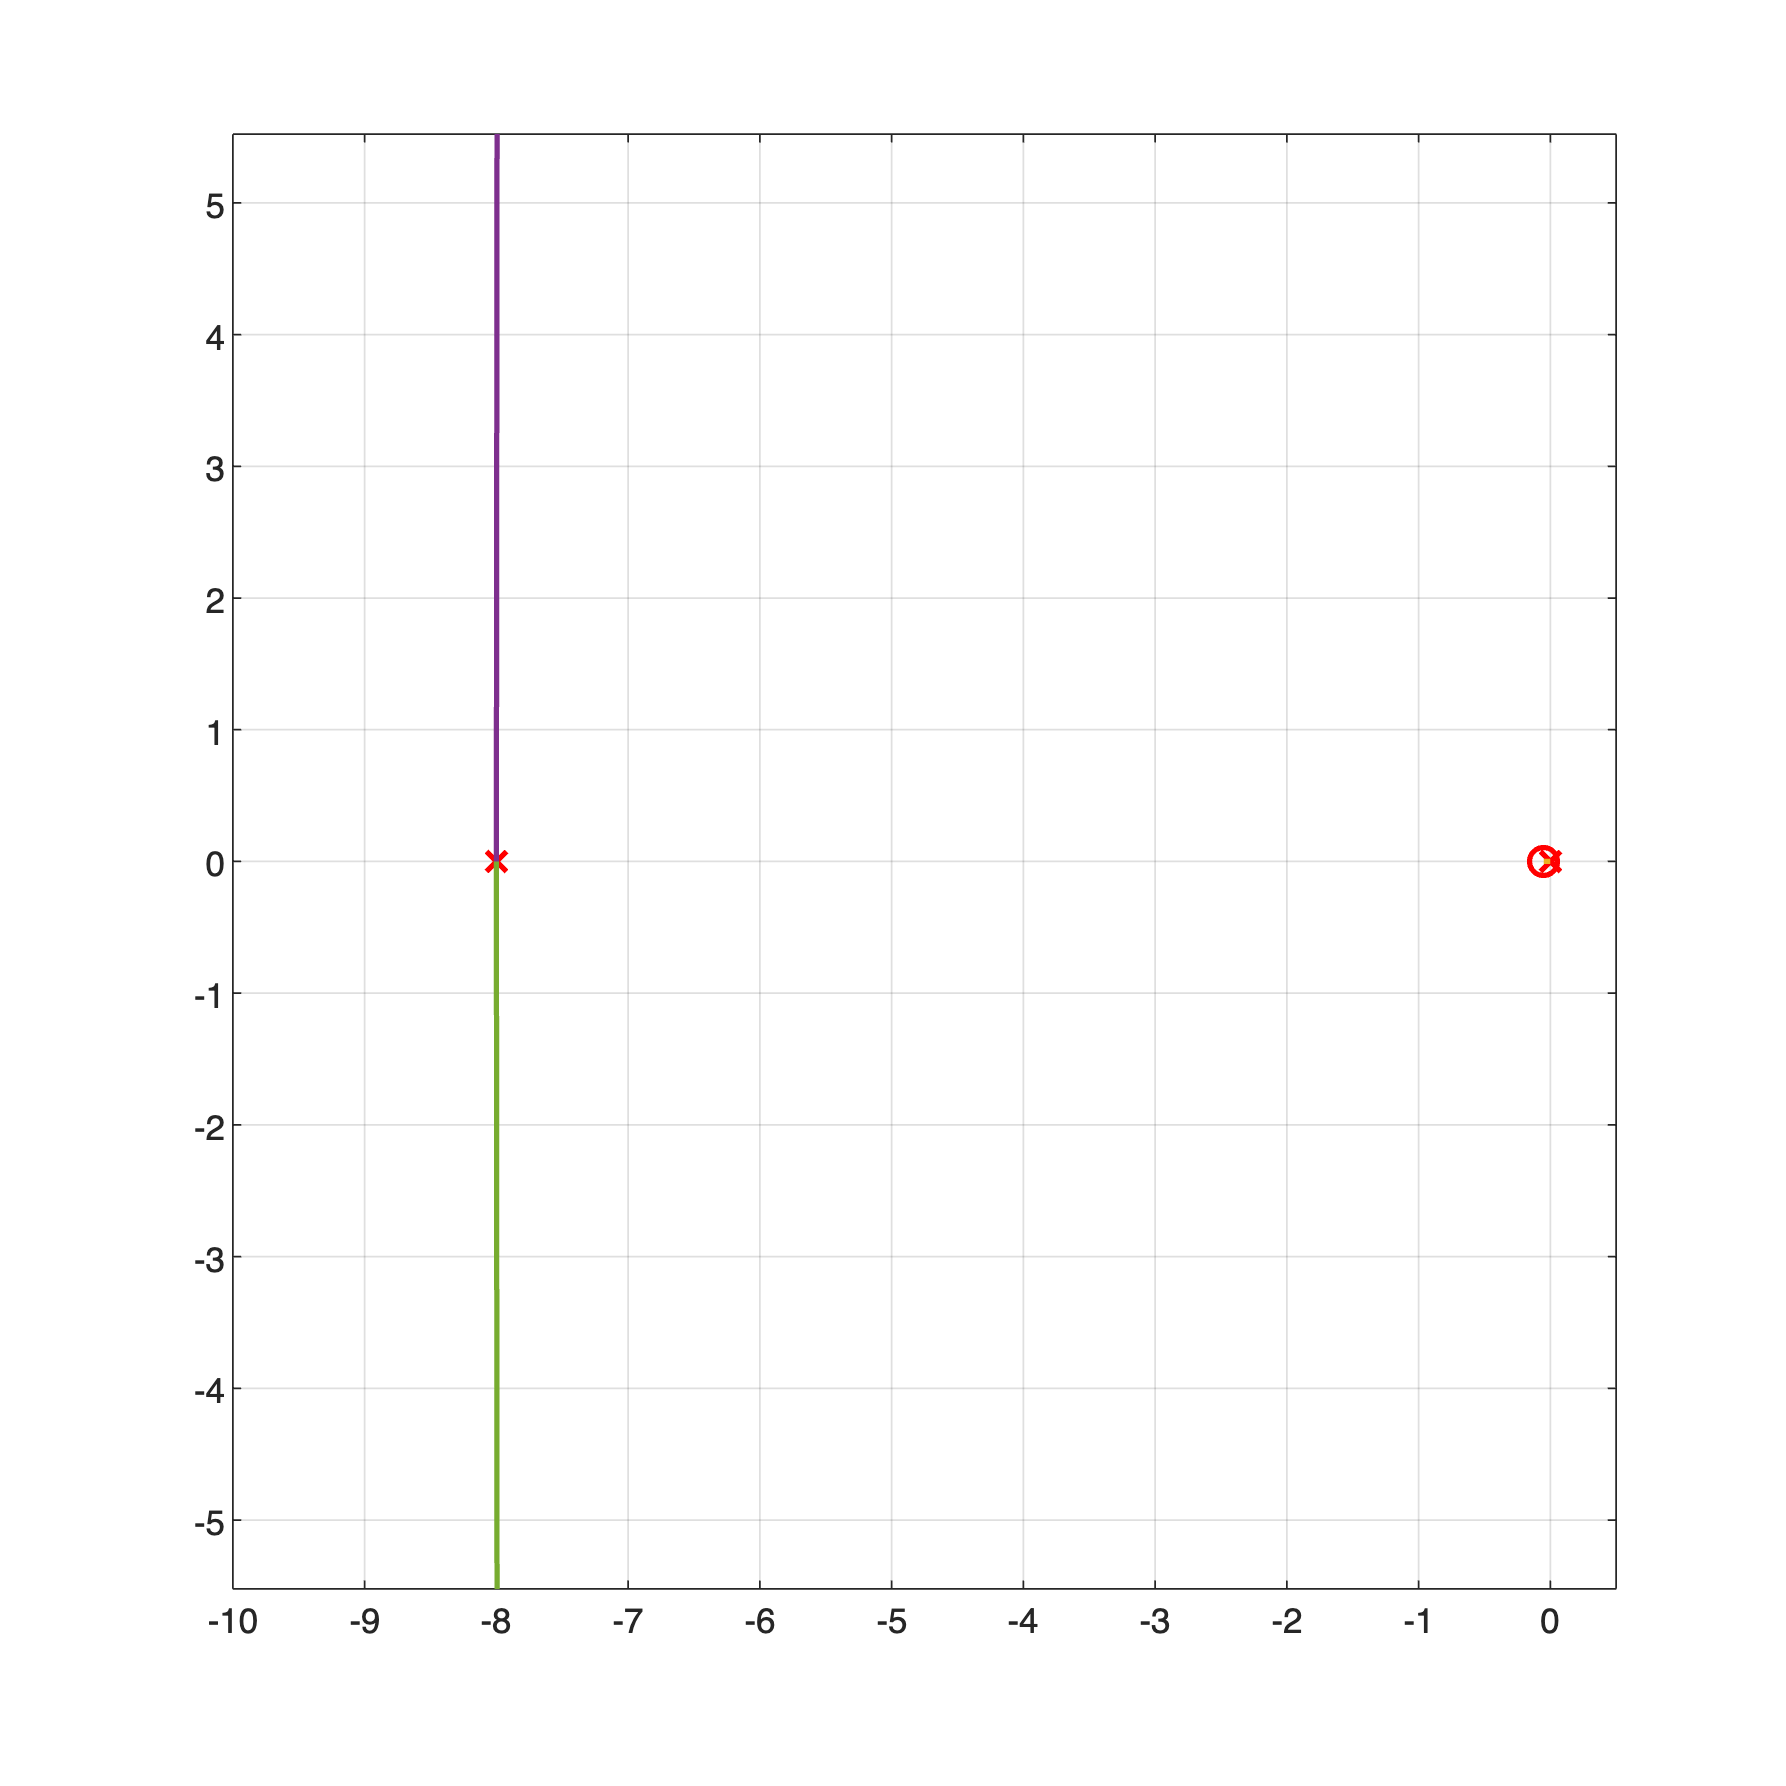

rhoSET = linspace(0, 1e3, 1e4); 
% 10000 values for the gain rho in the Direct RL
% starting from the min value that allows to meet 
% the requirement (Q1.1)
[DRL_L1, ~] = rlocus(L1s, rhoSET);

figure('Units','centimeters', 'Position',[0.1,0.1, 18, 18]);
% let's start with zeros & poles 
h_s1 = plot(real(zL1),imag(zL1),'ro', ...
    real(pL1),imag(pL1),'rx', ...
    'MarkerSize',8, 'LineWidth',1.5); 
hold on;
% L1s is a TF with only 1 zero and 1 pole, 
% so there are no singular points, no centroid,
% and no asymptotes.

% the Direct RL
for n=1:size(DRL_L1,1)
    h_rld1 = plot( real(DRL_L1(n,:)),imag(DRL_L1(n,:)), ...
               'LineWidth',1.5 );
end
grid on; hold off; axis equal;
zoom on; xlim([-10, +0.5]);

**Remark**: the closed-loop system is asymptotically stable $\forall \mu_{C} > 0$.

**The Bode Diagrams**

Let's explore the Bode Frequency Response Diagram:

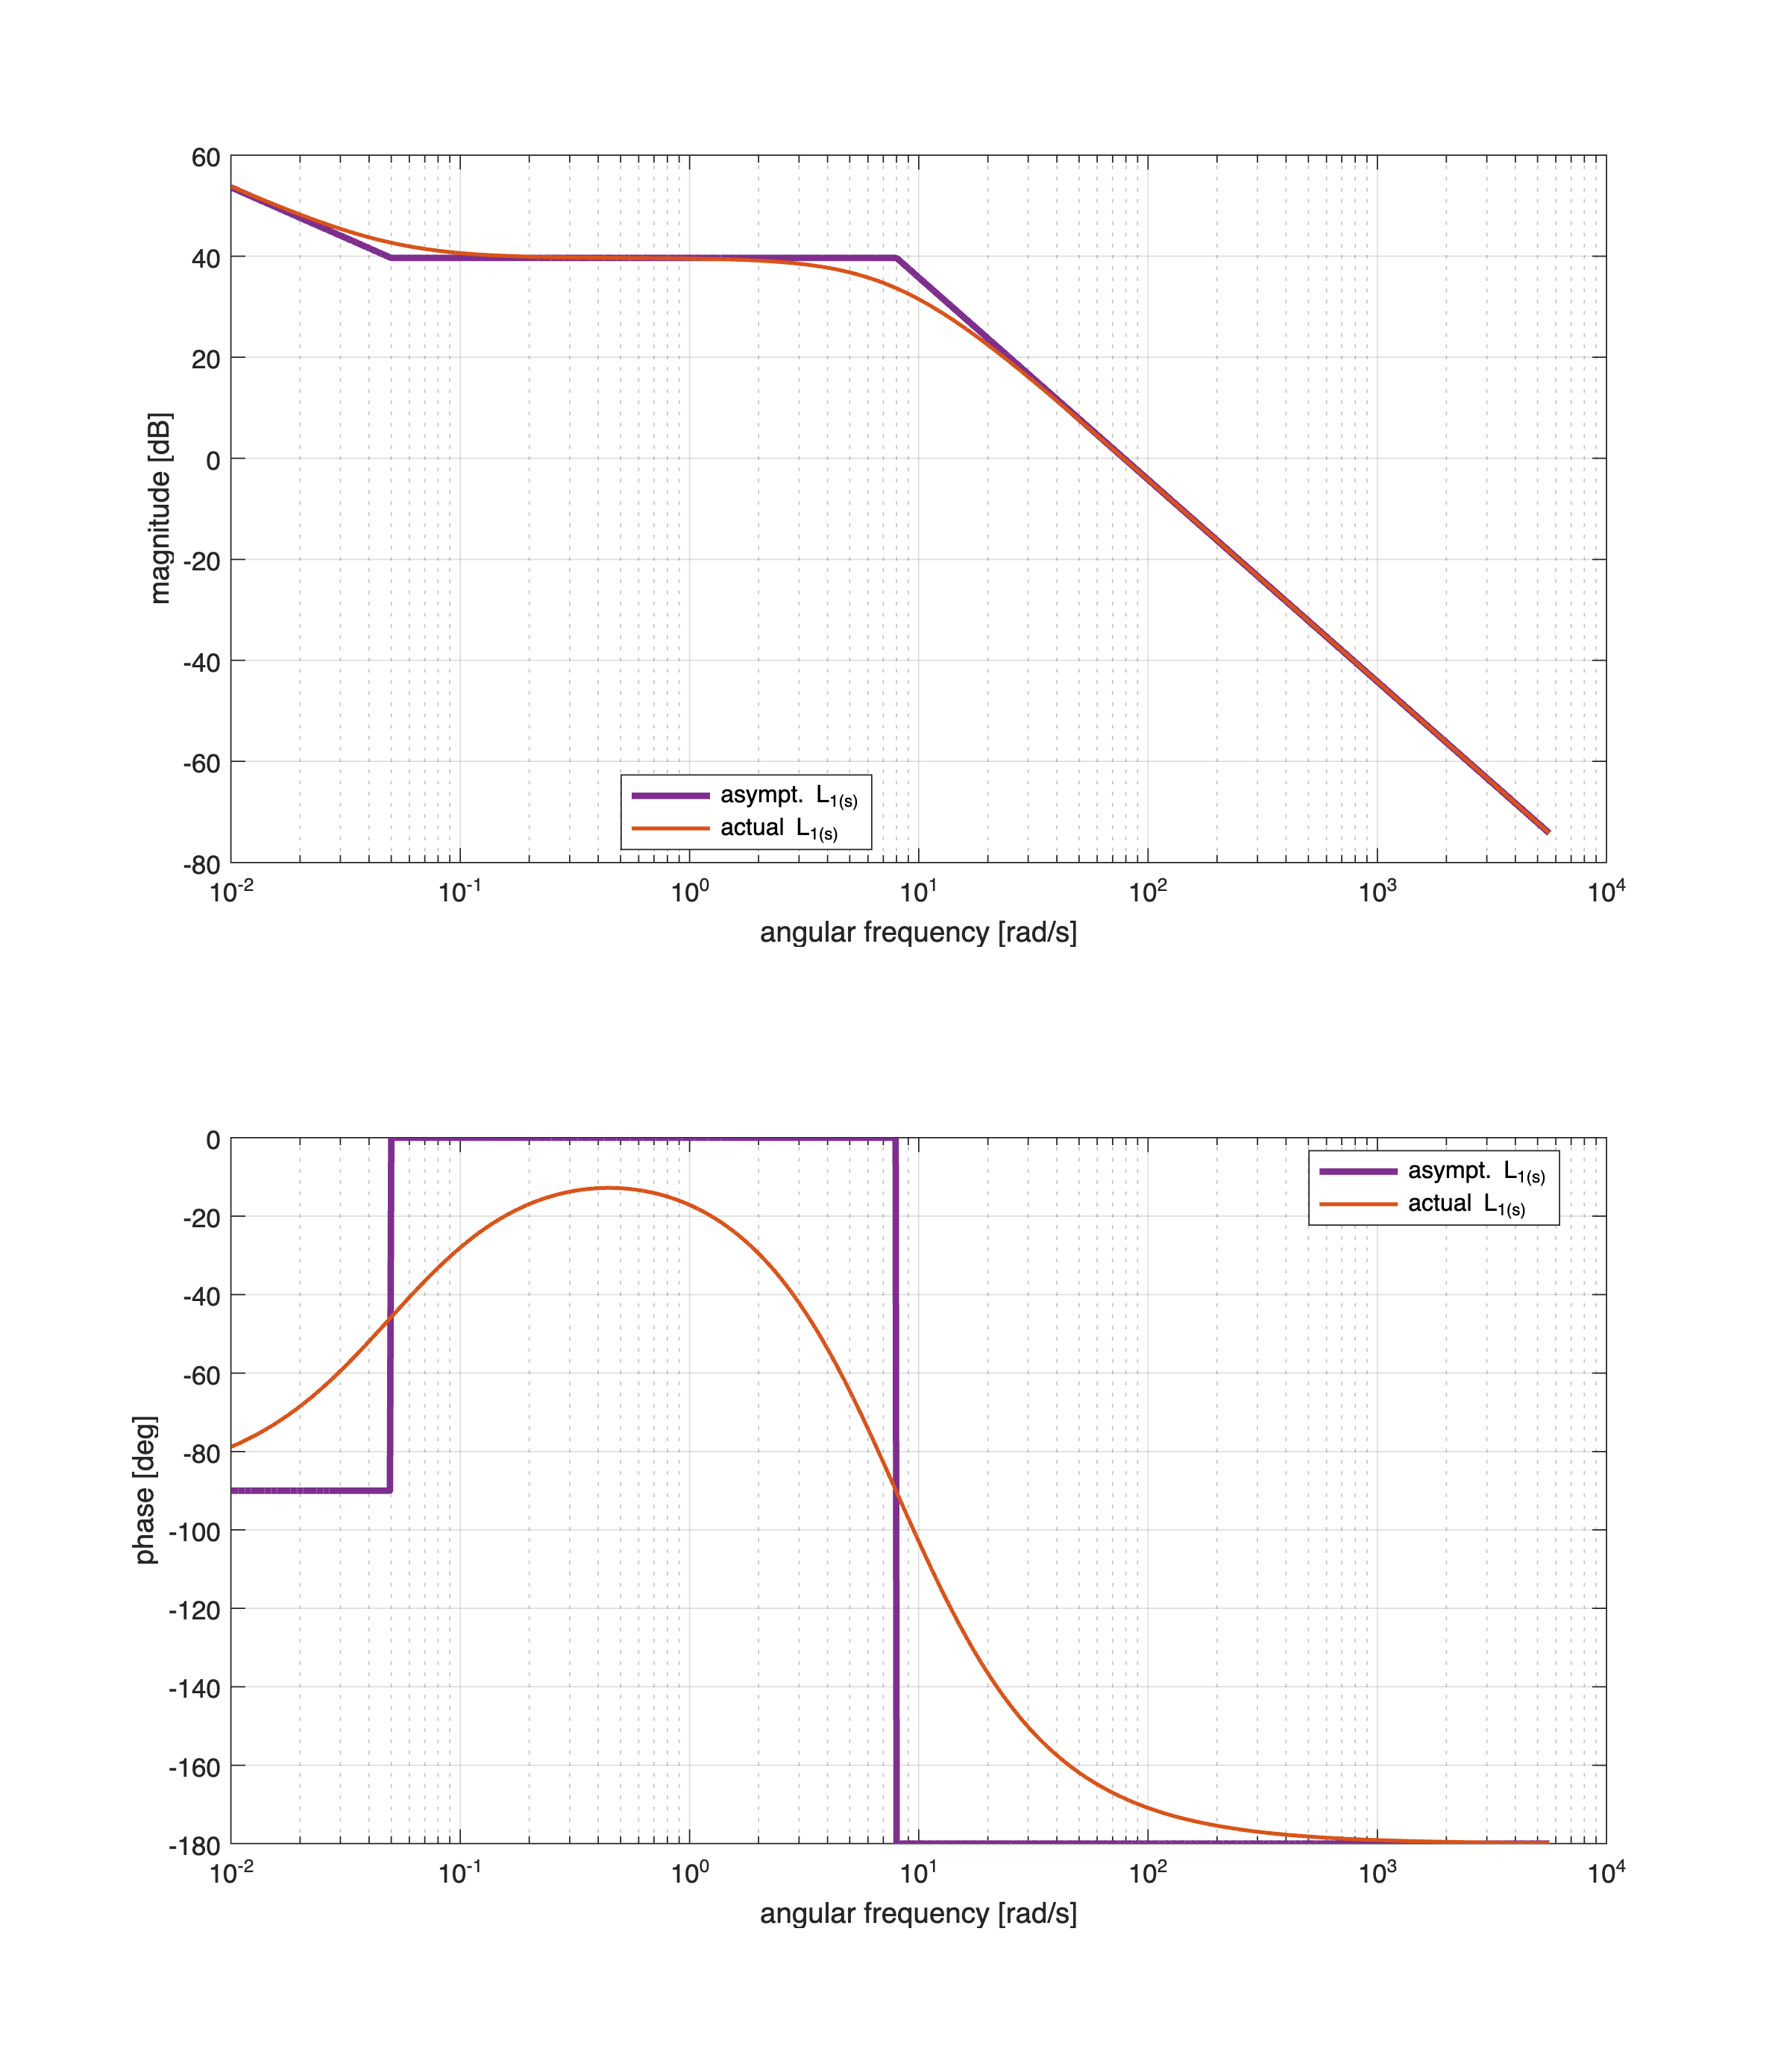

omVALS = logspace(-2,3.75, 1e5); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

[hax1, hax2] = drawBodediagrams(L1s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf);

legend(hax1,  'asympt. L_1(s)', 'actual L_1(s)', ...
             'Location', 'best');

legend(hax2,  'asympt. L_1(s)', 'actual L_1(s)', ...
             'Location', 'best');

The dynamic requirements are not completely fulfilled:

- according to (Q1.2) $\left\vert L(j\,\omega)\right\vert \ge 26\,\text{dB} \, , \; \omega \in \left[0.1\,,\; 1.0\right]\; \text{rad/s}$. This requirement could be easily fulfilled, by adjusting the gain constant $\mu_C$;

- according to (Q1.2) $\left\vert L(j\,\omega)\right\vert \le -28\,\text{dB} \, , \; \omega \in \left[600.0\,,\; 1200.0\right]\; \text{rad/s}$.  

- according to (Q1.3) $\omega_C \le 20\;\text{rad/s}$. Using the actual controller, we cannot meet this requirement unless we no longer meet the former requirements.

Let's modify the controller $C(s)$, by modifying the gain $\mu_C$ and introducing some zeros and poles in the dynamic controller $C_2(s)$.

#### The Dynamic Design	

Let's start with $C_2(s) = \frac{(1+0.125\,s)^2}{(1+0.25\,s)\,(1+0.01\,s)}$. 

The **key idea** is to keep the "almost constant" amplification of $L(j\omega)$ in the range $ \omega \in \left[0.1\,,\; 1.0\right]\; \text{rad/s}$, but then to improve the attenuation when $\omega \ge 100$ rad/s.

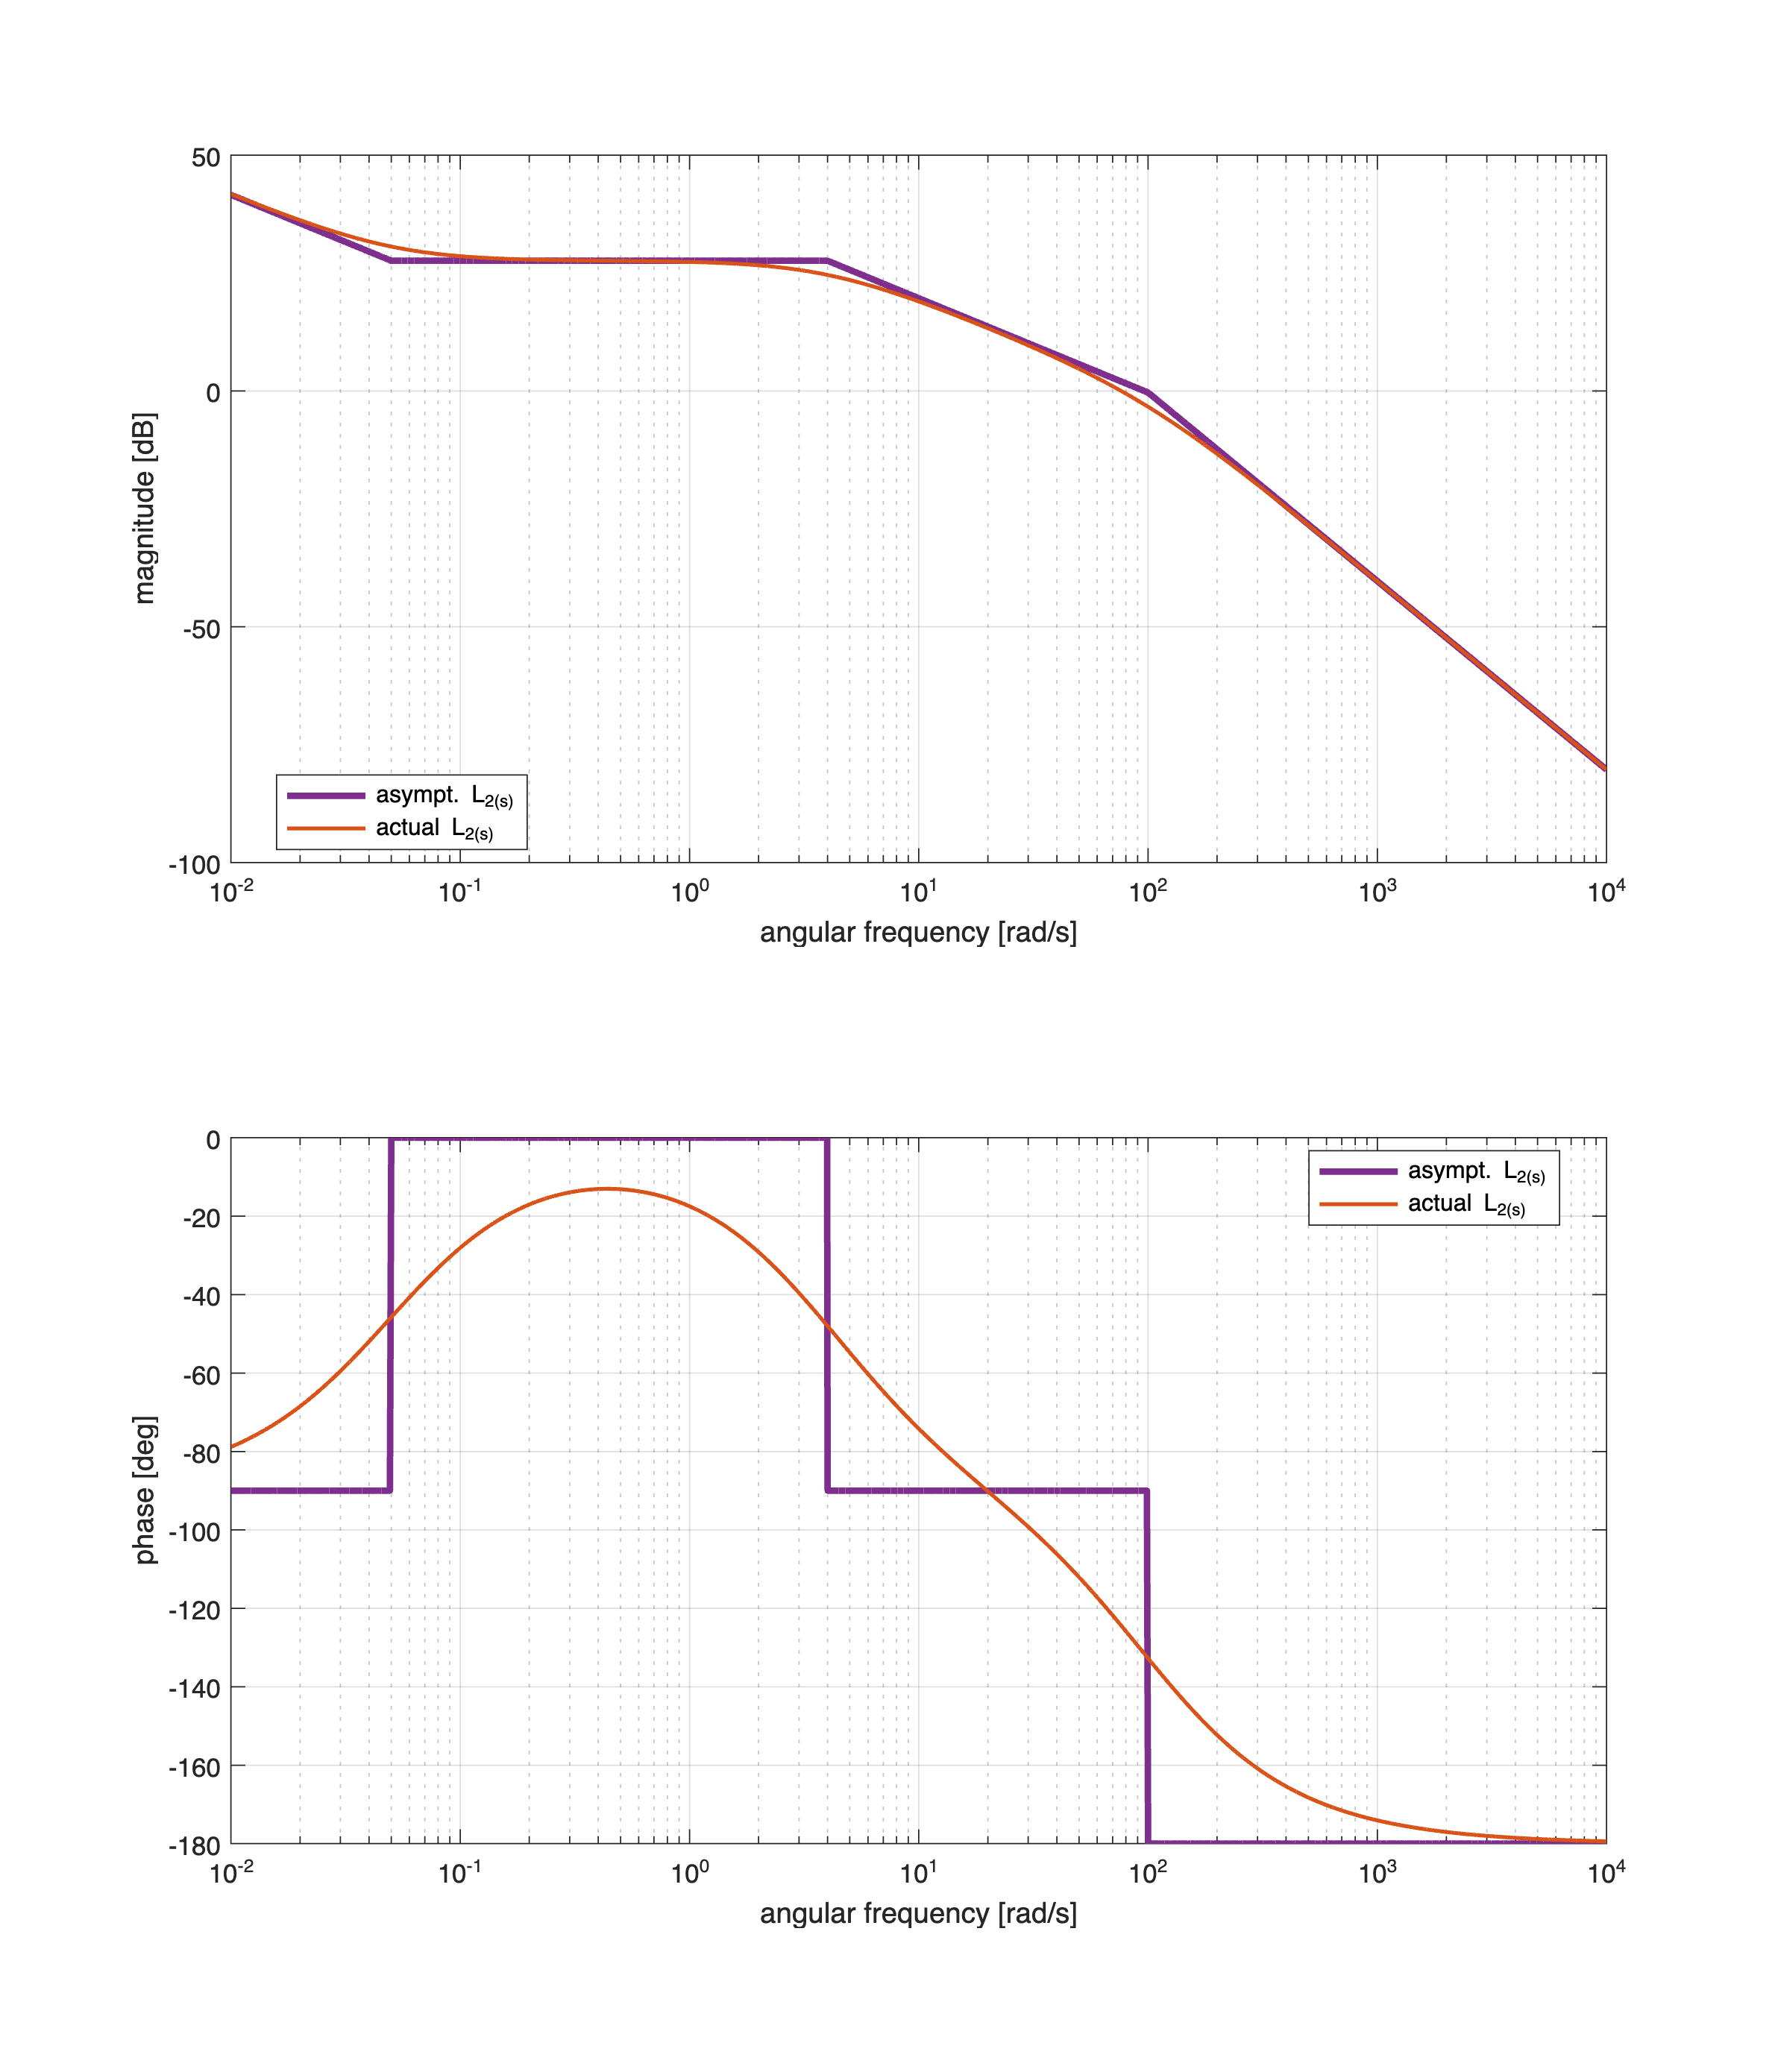

muC1 = 0.25; % improve the amplification
C1s = muC1/s; % a pure I controller (the static controller)
C2s = (1+0.125*s)^2/(1+0.25*s)/(1+0.01*s); % the dynamic controller: a pure P gain
Cs = C1s * C2s;

L2s = minreal(Cs*Gs); % the open-loop TF
zL2 = zero(L2s);
pL2 = pole(L2s);

omVALS = logspace(-2,4, 1e5); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

[hax1, hax2] = drawBodediagrams(L2s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf);

legend(hax1,  'asympt. L_2(s)', 'actual L_2(s)', ...
             'Location', 'best');

legend(hax2,  'asympt. L_2(s)', 'actual L_2(s)', ...
             'Location', 'best');

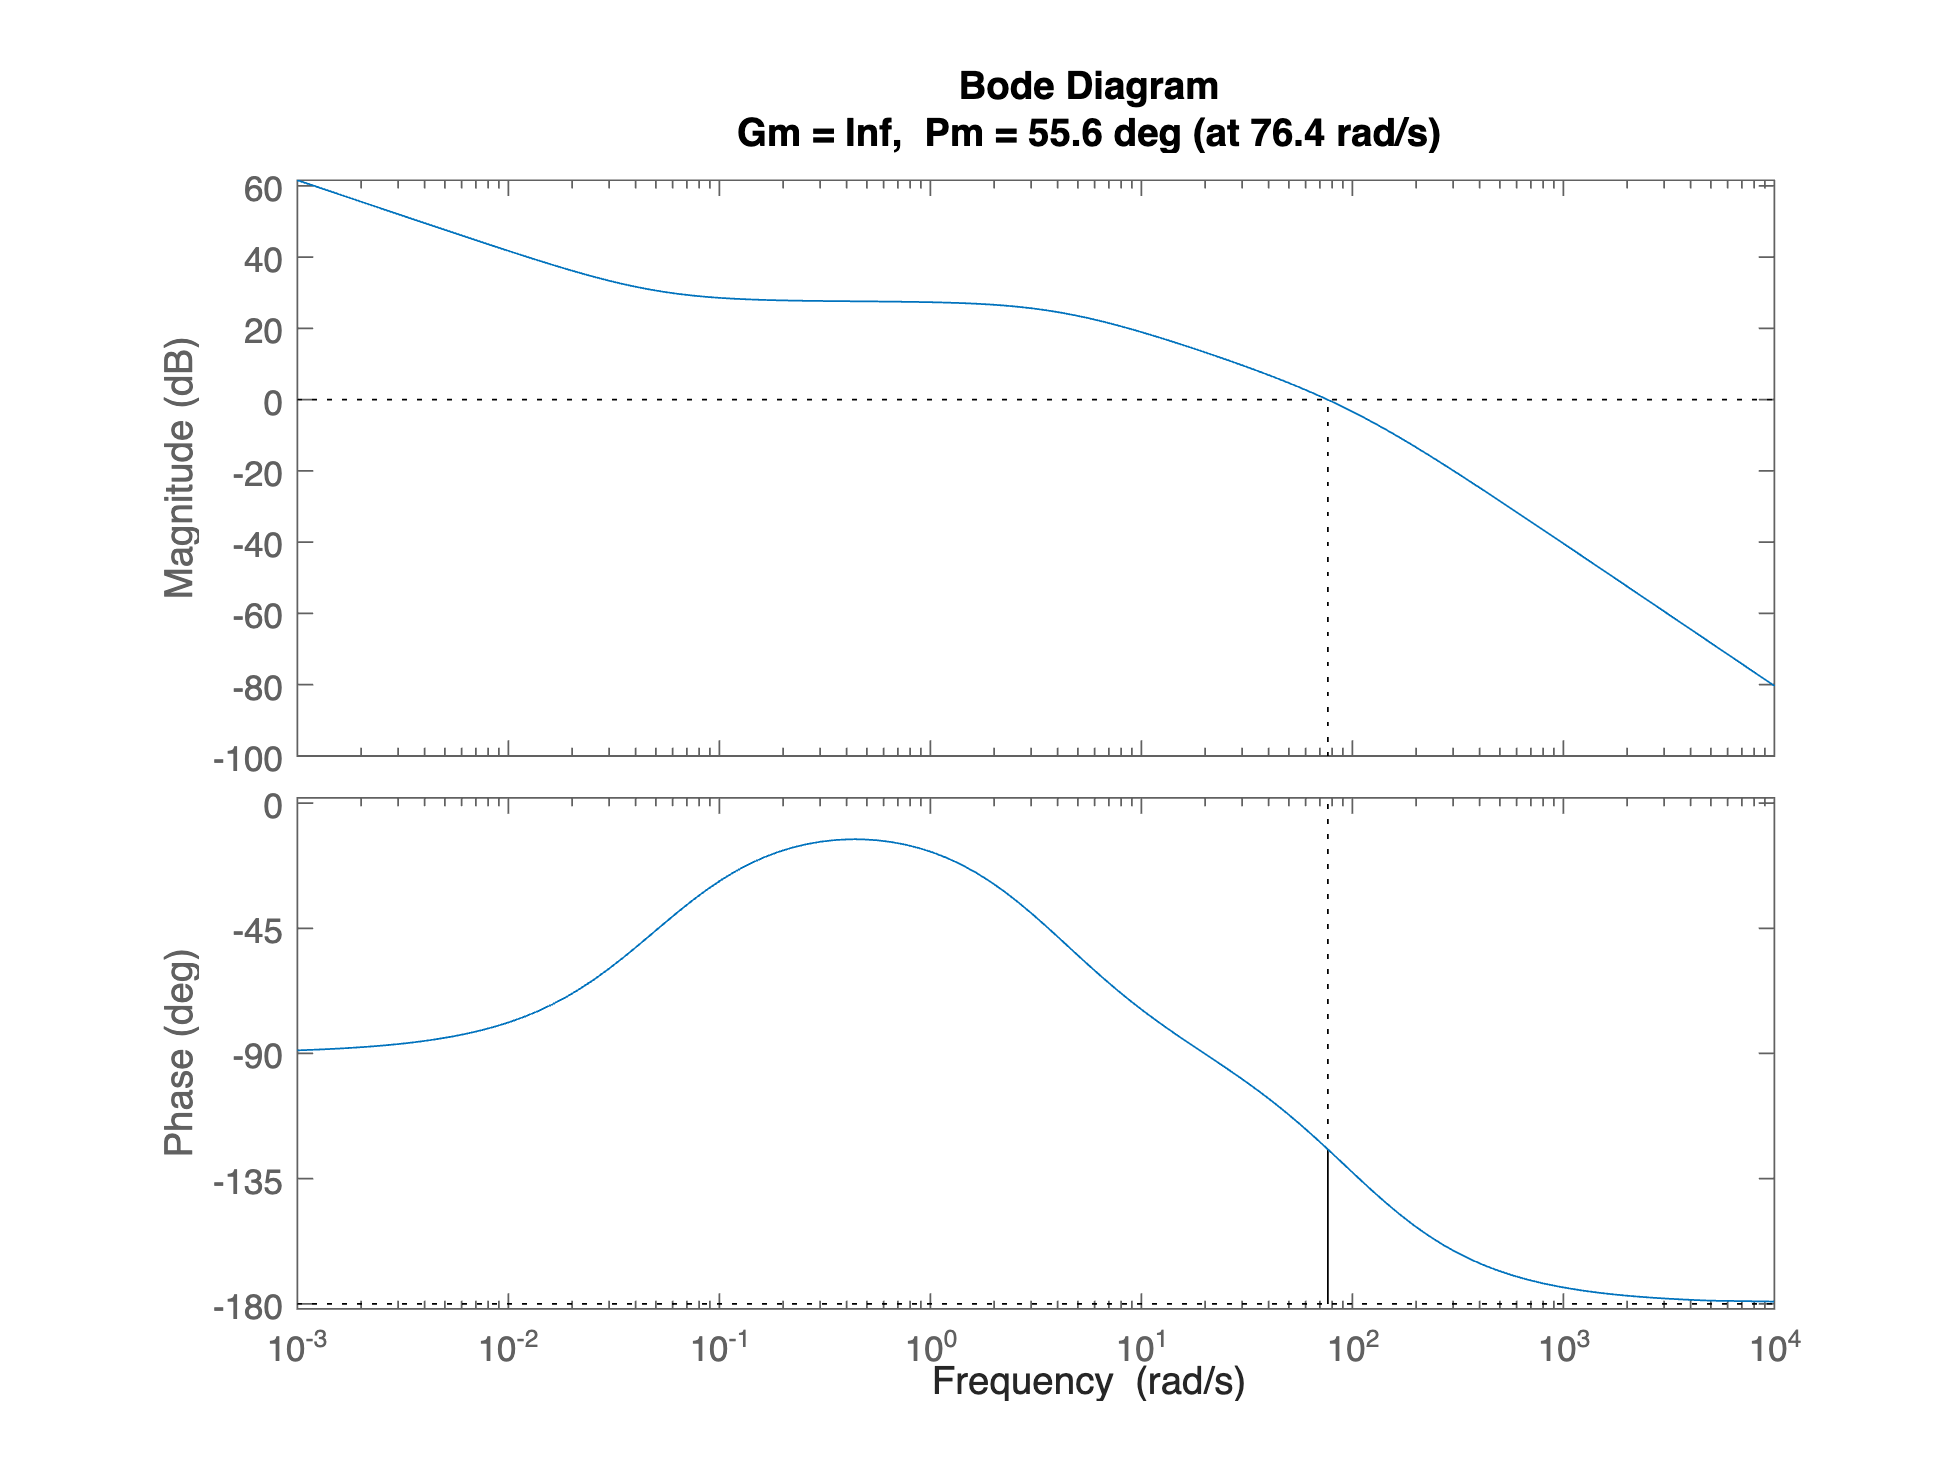


figure;margin(L2s)

**Tuning the Solution**

Let's tune the candidate solution using the Control System Designer app

controlSystemDesigner(Gs, Cs)


Refer to `ControlSystemDesignerSession_FINAL_TUNING_V1.mat`

### A Different Solution

#### Design by Cancellation

Let's cancel the plant dynamics using the controller $C_2(s)$:


$$C(s) = \frac{\mu_C}{s}\,\frac{(1+0.125\,s)^2}{(1+20\,s)}$$


Thus


$$L(s) = C(s) \cdot G(s) = \frac{4.815\,\mu_C}{s}$$


The requirements (Q1.1) and (Q1.3) have been meet. In order to fulfill the requirement (Q1.2) we have to fine tuning $\mu_C$.

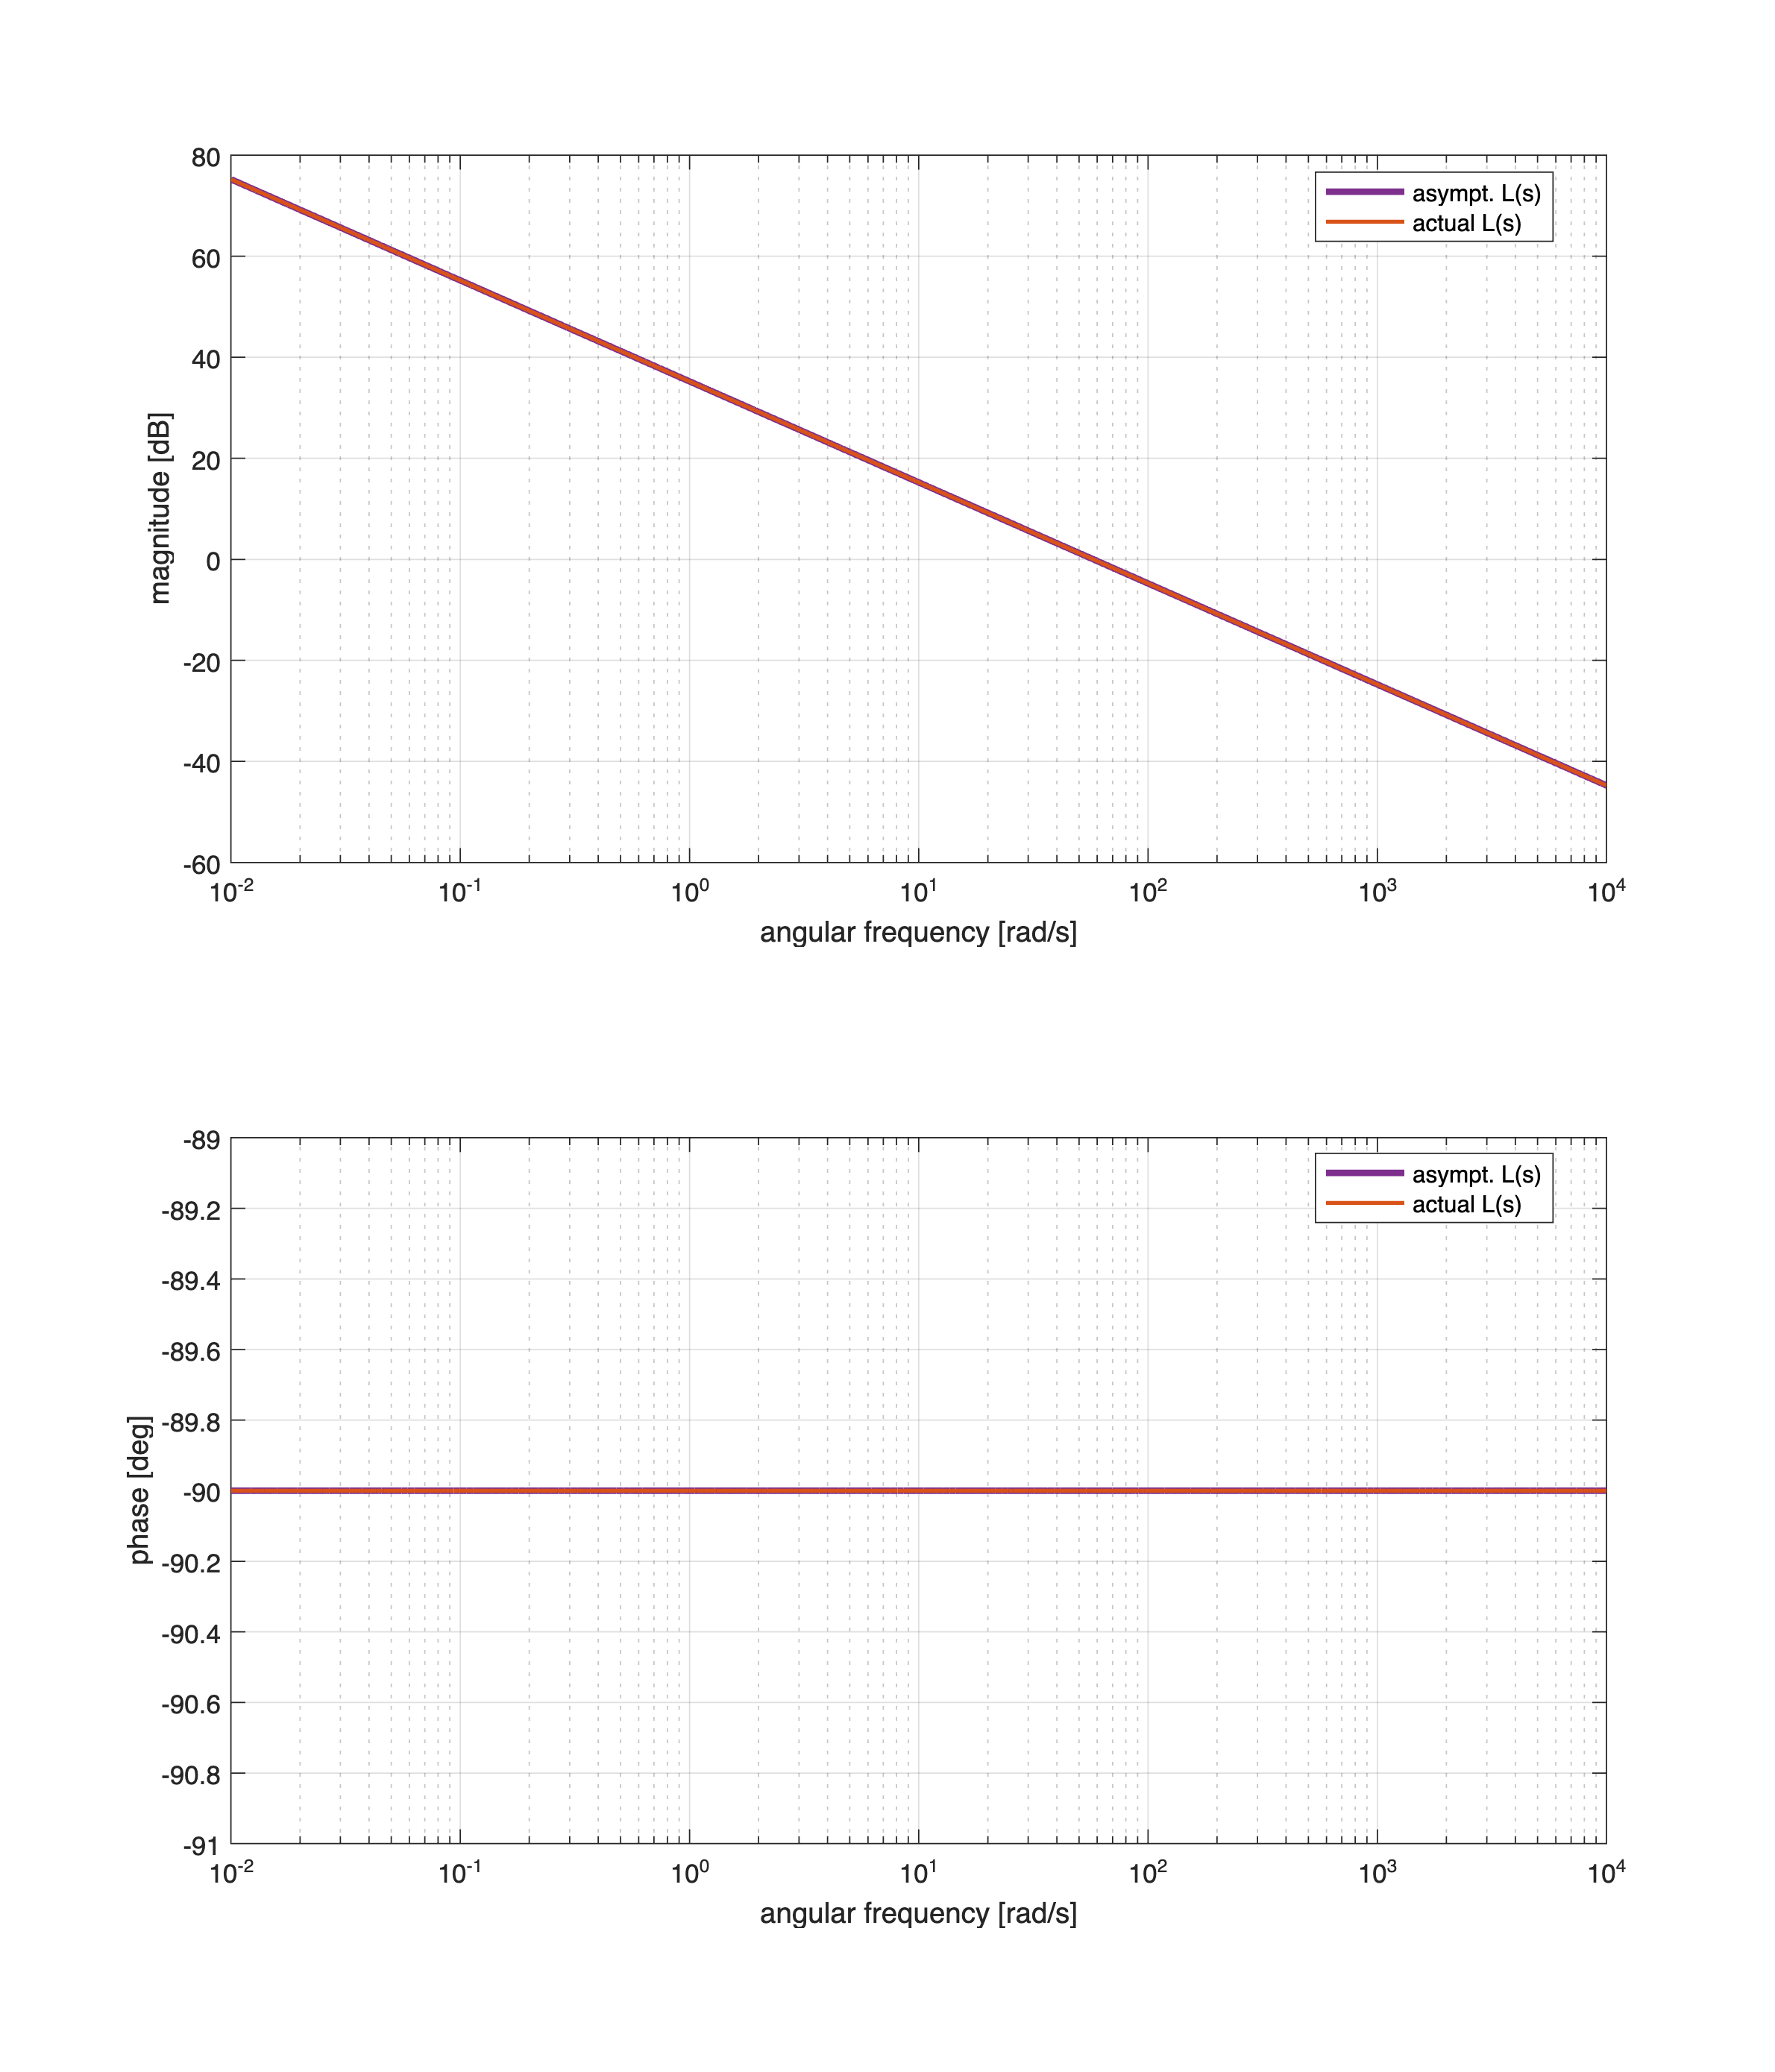

muC1 = 12; % improve the amplification
C1s = muC1/s; % a pure I controller (the static controller)
C2s = (1+0.125*s)^2/(1+20*s); % the dynamic controller
Cs = C1s * C2s;

Ls = minreal(Cs*Gs); % the open-loop TF
zL = zero(Ls);
pL = pole(Ls);

omVALS = logspace(-2,4, 1e5); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

[hax1, hax2] = drawBodediagrams(Ls, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf);

legend(hax1,  'asympt. L(s)', 'actual L(s)', ...
             'Location', 'best');

legend(hax2,  'asympt. L(s)', 'actual L(s)', ...
             'Location', 'best');

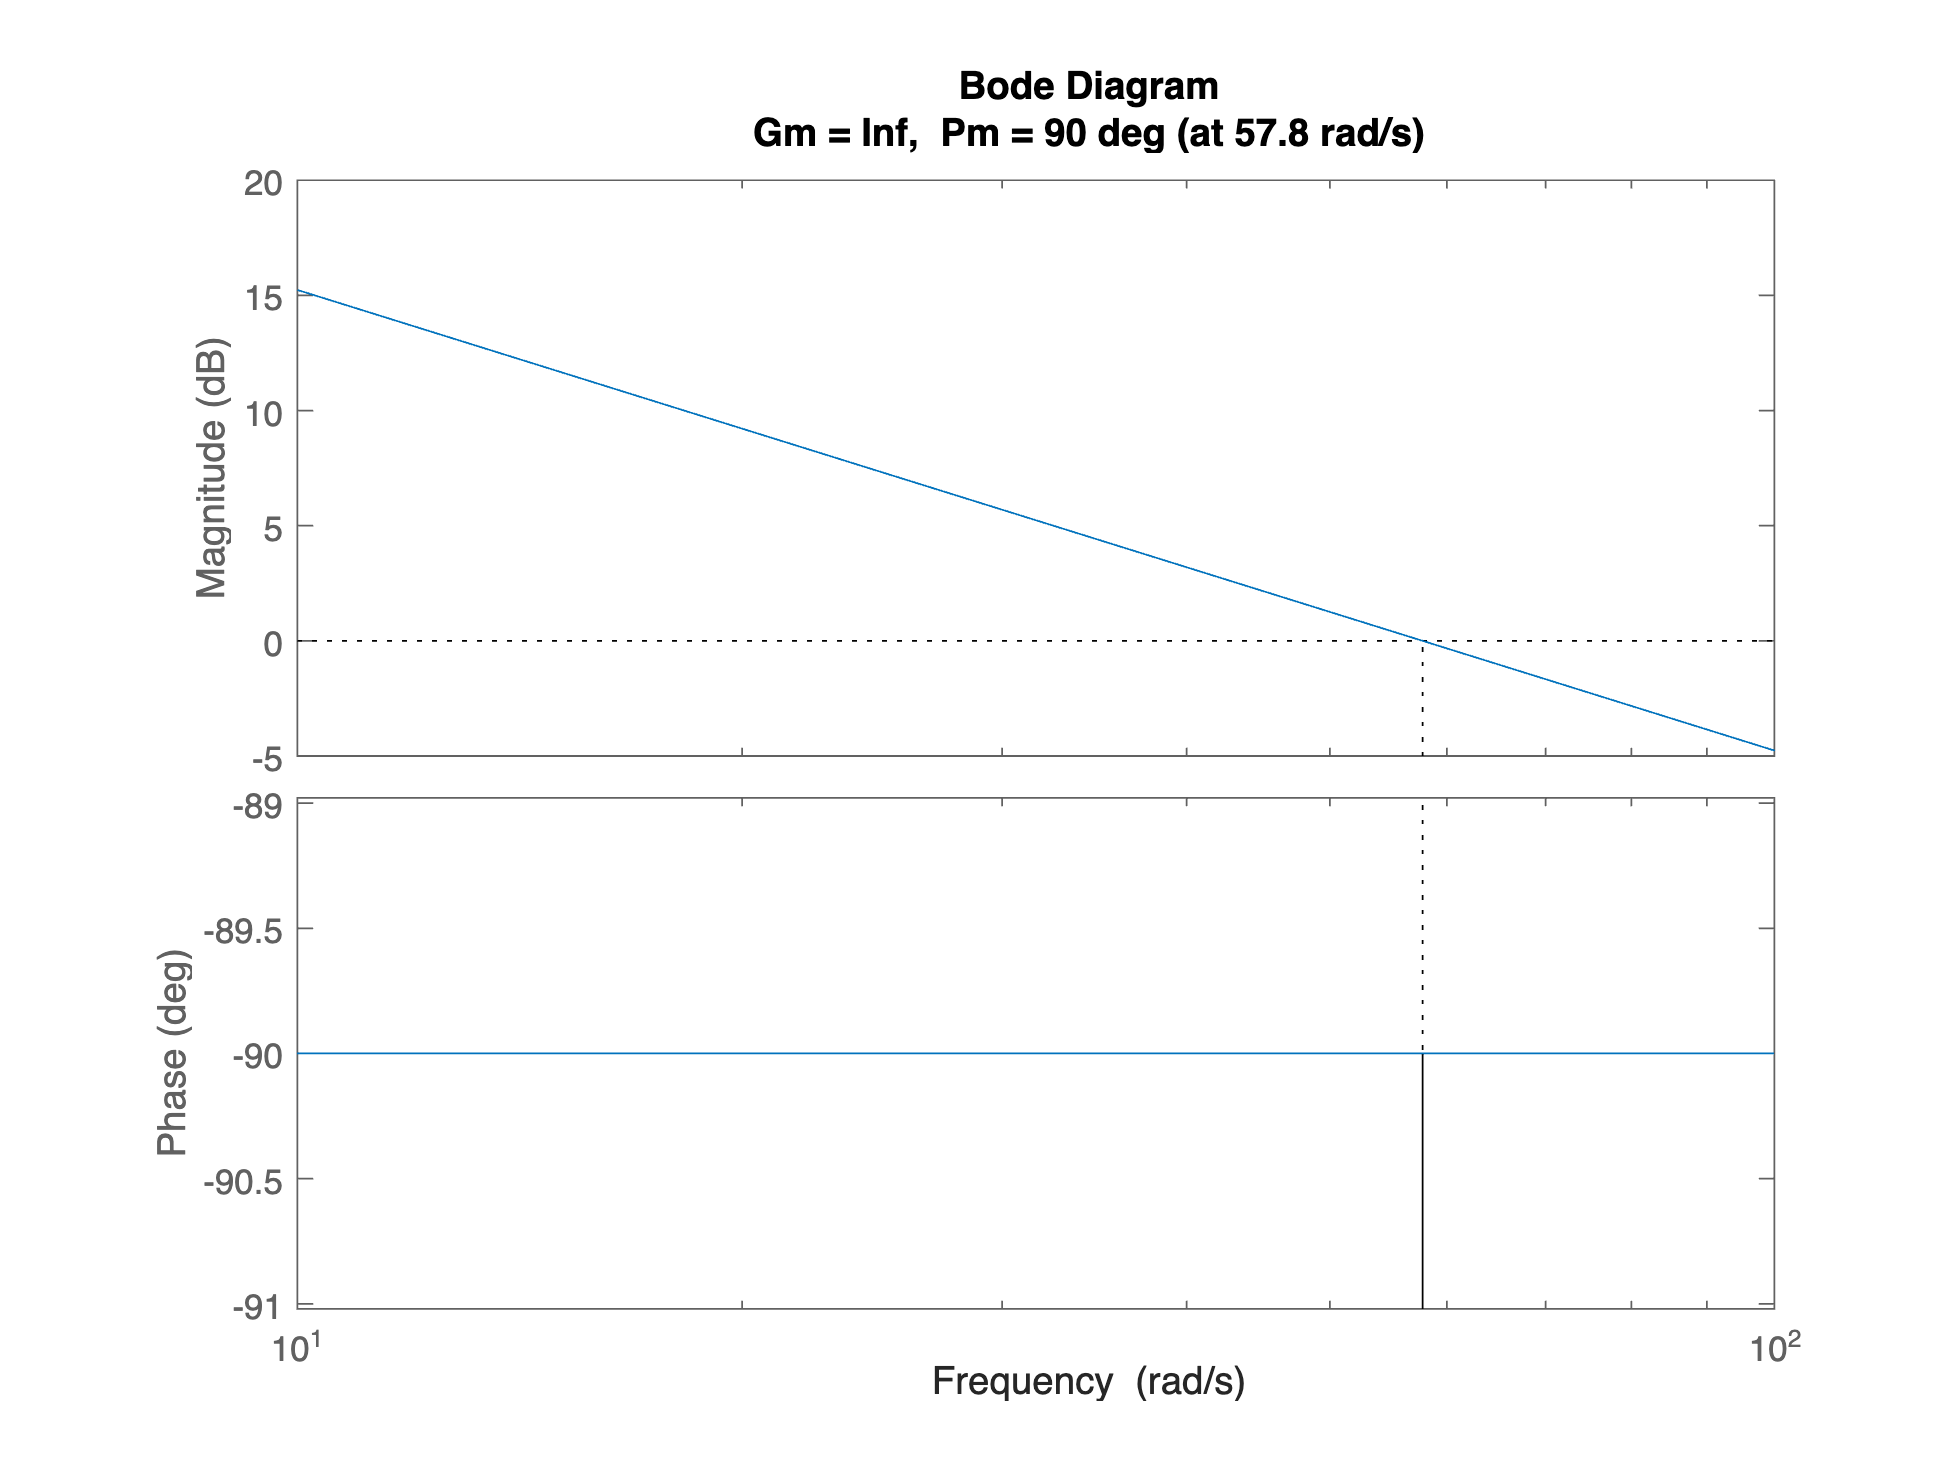


figure;margin(Ls)

**Tuning the Solution**

Let's tune the candidate solution using the Control System Designer app

controlSystemDesigner(Gs, Cs)


Refer to `ControlSystemDesignerSession_FINAL_TUNING_V2.mat`